# First order models and behaviour

This livescript is a brief manual in support of the app ***firstordermodel_behaviour.mlapp***.   This is a simple interface to understand the modelling and behaviour of simple 1st order models represented in time constant form and support students in being able to make quick and accurate estimates of the time constant and gain.    

More extensive background and instruction on the use of MATLAB can be found in the files: ***firstordermodels_responses_analysis_and_feedback.mlx*** and ***firstordermodels_in_matlab.mlx***.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context

- Time constant and gain formulation

- Behaviour and the time constant form

- App file and usage

## 1. Engineering context

We consider a generic first order differential equation model, state ***x***, with a constant input ***f***, for example:


$$a\frac{\textrm{dx}}{\textrm{dt}}+\textrm{bx}=\textrm{cf}$$


For simplicity this file will use $f=1$, and simple scaling can be used to find solutions for other constant values.

## 2. Time constant and gain formulation

As the basic model is a 1st order differential equation, it is common place to model these in time constant form.


$$a\frac{\textrm{dx}}{\textrm{dt}}+\textrm{bx}=\textrm{cf}\;\;\Leftrightarrow \;\;\;\frac{a}{b}\frac{\textrm{dx}}{\textrm{dt}}+x=\frac{c}{b}f\;\;\;\Leftrightarrow \;\;\;\;T\frac{\textrm{dv}}{\textrm{dt}}+v=\textrm{Cf}$$


where $T=\frac{a}{b}$ is the time constant and $C=\frac{c}{b}$ is the steady-state system gain (often just denoted as gain).

Time constant form is useful for understanding behaviours.

## 3. Behaviour and the time constant form

For more extensive notes, see the file: ***firstordermodels_responses_analysis_and_feedback.mlx***

The time constant *T *gives an indicator of the convergence rate (typically about 3 time constants to be within 5% of steady-state) and the system gain C indicates  the expected steady-state value of the system state (with no disturbances) and  ***f=1 ***(a more generic formula for the steady state is ***Cf***). A common way of estimating the time constant is to note that the system moves 63% of the way from the initial condition to the steady-state in one time constant. This is evident from the generic solution, for constant ***f***, below.


$$\left\lbrace x\left(t\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-\frac{t}{T}} +\textrm{Cf}\right\rbrace \;\;\Rightarrow \;\;\left\lbrace x\left(T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-1} +\textrm{Cf}\right\rbrace \;\;\;$$


Hence:  $x\left(T\right)=\left\lbrack \textrm{Cf}-x\left(0\right)\right\rbrack 0\ldotp 63+x\left(0\right)$

One can thus form an estimate of the time constant by determining the time associated to a 63% movement. Similarly an estimate of C is given from:


$$\textrm{Cf}=\lim_{t\longrightarrow \infty } x\left(t\right)$$


The figure below illustrates these two computations on a simple example.

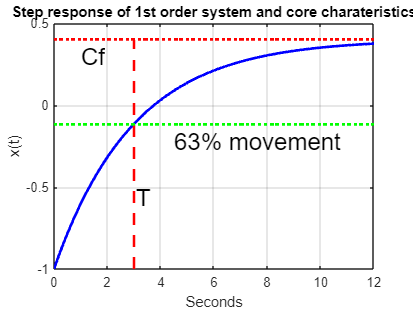

% determine responses (assume f=1)
T=3;
C=0.4;
x0=-1;
t=linspace(0,4*T,101);
x=(x0-C)*exp(-t/T) + C;
x63 = C+(x0-C)*.37;  
figure;clf
plot(t,x,'b','linewidth',2); hold on
aa=plot([T,T],[x0,C],'r--');
bb=plot([0,4*T],[x63,x63],'g:',[0,4*T],[C,C],'r:');
grid
set(bb,'linewidth',2);
set(aa,'linewidth',2);
xlabel('Seconds')
ylabel('x(t)')
text(T/3,C-0.1,'Cf','fontsize',18);
ylim([x0,0.5]);
text(T*1.02,x0+(x63-x0)*0.5,'T','fontsize',18)
text(T*1.5,x63-0.1,'63% movement','fontsize',18)
title('Step response of 1st order system and core charateristics')

## 4. App file and usage

The app allows the user to create a random example using the bright yellow button. The response appears with circles.

The user then selects values in the sliders to estimate the gain and time constant, and uses the bright pink 'check my estimates' button to overlay the associated response. The figure keeps track of the user guesses through the legend.

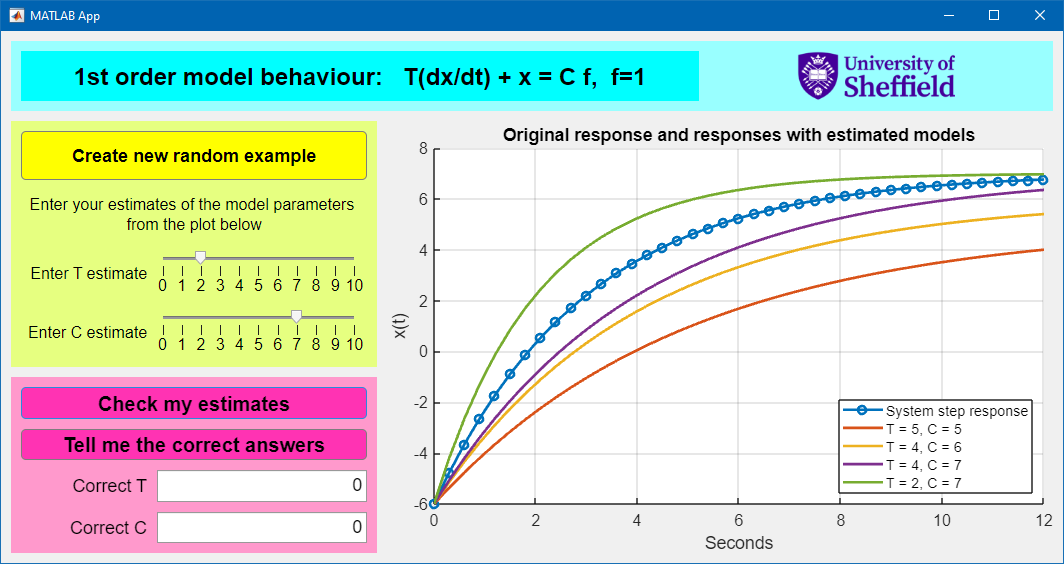

The user can check for the correct answer using the  final pink button, which then overlays the core computations for clarity, as well as giving the correct values for time constant and gain.